clear; % FIX IN REAL CODE = FIRC

# Tutorial 4 - Attitude Determination and Control Systems

## **Introduction**

In this tutorial, I will make use of integration, separate function, and the **area** plot in MATLAB to calculate the magnitudes of gravity and drag torque and three different altitudes to analyse which altitude is best and how much momentum store the on-board reaction wheels will have to have in order to successfully carry out the Sentinel 6B mission. 

This mission design process requires specific attention being paid towards the Attitude Determination and Control System (ADCS) in order to be able to carry out crucial tasks that are essential to the success of the mission. Without proper or sufficient momentum storage, the spacecraft might be unable to point towards the correct location to conduct science experiments or communicate with the ground station. Alternatively, if the reaction wheels are too powerful, this adds unnecessary mass to the system, meaning that more fuel will be required, increasing mass again and driving costs of manufacturing and cost up. 

Therefore, it is absolutely critical to be able to determine what the best reaction wheel for the job is, and this can only be accomplished through careful analysis of the properties of the spacecraft itself. 

### **Task 1 - Defining Inputs**

Most of the inputs that are being defined in this task are given, however orbital velocity at each altitude will have to be calculated. Additionally, I have not created any array with three indices, as this can be done automatically later on. Instead, I have just declared two empty arrays, one for gravity torque and one for drag torque, both of which will be filled later on with the appropriate values. I have done this to be able to define the gravity and drag torque alongside all other inputs that will be required throughout the tutorial, but these empty arrays don't hold any practical value to the execution of the code. 

altitudes = [1000000, 1336000, 2000000];                % [m] Altitude array
T_g = [];                                               % torque due to gravity array
T_D = [];                                               % torque due to atmospheric drag array
I_yy = 25; I_zz = 40;                                   % [kgm^-2] Mass moments of inertia
C_d = 2.2;                                              % [] Coefficient of drag
area_surface = 3.35; area_total = area_surface * 6;     % FIRC remove
rho_alts = [3*10^-15, 8.5*10^-16, 7*10^-17];            % [kgm^-3] Densities at various altitudes
mu = 3.986*10^14;                                       % [m^3s^-2] Redefined gravitational parameter in metres
R_earth = 6371000;                                      % [m] Redefined earth radius in metres

Calculating orbital velocity simply requires using the equation found in the coursenotes. 

Equation (3.8)

#### 
$$v=\sqrt{\frac{\mu }{r}}$$


Gravitational parameter $\mu$

    
$$\mu =3\ldotp 986*{10}^{14} m^3 s^{-2}$$


Orbital radius $r$

    
$$\begin{array}{l}
r=R_{\textrm{earth}} +\textrm{altitude}\\
r=6371+\left\lbrack 1000,1336,2000\right\rbrack =\left\lbrack 7371,7707,8371\right\rbrack *{10}^3 m
\end{array}$$


Orbital velocity $v$


$$v=\sqrt{\frac{3\ldotp 986*{10}^{14} }{\left\lbrack 7371,7707,8371\right\rbrack *{10}^3 }}=\left\lbrack 7354,7192,6901\right\rbrack *{10}^3 {\textrm{ms}}^{-1}$$


vel_alts = [sqrt(mu./(R_earth+altitudes))];             % [ms^-1] Velocity array at each altitude

Sentinel 6A satellite did not have any extendable solar panels, and the surface area of this satellite is only roughly 20m^2, so it is clear that this is not a particularly large satellite with excessively sized surfaces of low mass. Therefore, it is valid to assume that the centre of mass is not very far from the centre of pressure. For this reason, I made an educated guess that they are 50cm apart.  

CgToCp = 0.5;                                           % [m] Distance between centre of mass and centre of pressure

### Task 2 - Find Gravity Torque

In tasks 3, 4, and 5, I have explained the function I use here to find a value for gravity torque. The function uses array multiplication to eliminate the need of a for loop, meaning that with one operation, all values in the **altitudes** array create an equally sized gravity torque array. 

Equation (9.6): 


$$T_{\textrm{Qg}} =\left(\frac{3\mu }{2R^3 }\right)\left|I_{\textrm{ZZ}} -I_{\textrm{YY}} \right|\sin \left(2\theta \right)$$


θ is the angle between the spacecraft's Z-axis and the local vertical axis.

For this analyis, I will assume the worst case scenario, which is when θ is 45 degrees, making sin(2θ) = 1, meaning that the torque due to gravity will be as large as it can be as the sin function does not exceed 1.  

### Task 3-7 are discussed at the bottom of the livescript

### Task 8 - Get Maximum Gravity and Drag Torques

To find the largest values of the torques, both due to gravity and due to air resistance, we simply equate the variable for maximum torque to their respective function outputs. Once again, there is no need for a loop as the functions themselves allow their outputs to be arrays. 

T_g = get_T_g(I_zz, I_yy, altitudes, mu, R_earth);
T_D = get_T_D(rho_alts, C_d, area_surface, vel_alts, CgToCp);

### Task 9 - Calculate Orbital Period

To calculate orbital period, I used the equation found in the course notes. 

$\tau =2\pi \sqrt{\frac{r^3 }{\mu }}$    (3.9)

This equation is for circular orbits, which is a valid assumption as any changes to apogee or perigee due to atmospheric drag will be negligible. 


$$\begin{array}{l}
\tau_{1000} =2\pi \sqrt{\frac{{\left(6371+1000\right)}^3 }{398600}}=6298\;\textrm{seconds}\\
\tau_{1336} =2\pi \sqrt{\frac{{\left(6371+1336\right)}^3 }{398600}}=6734\;\textrm{seconds}\\
\tau_{2000} =2\pi \sqrt{\frac{{\left(6371+2000\right)}^3 }{398600}}=7622\;\textrm{seconds}
\end{array}$$


This operation will be carried out using array multiplication and the period of each orbit will be stored in an array where the index corresponds to the index in the altitude array, so the first value in the orbital period array will be the period for the altitude found in the first index of the altitude array. 

periods = 2.*pi.*sqrt((R_earth+altitudes).^3./mu); % [s] Array of orbital periods

### Task 10 - Create Function for Total Torque

Now to calculate the change of torque over a period, we know that the torque due to gravity will change depending on the spacecraft's current orbital position, and since the orbital location is a function of time, we can relate the max value of torque due to gravity that was found and multiply it by the sinusoidal function of time. 

Torque due to atmospheric drag, on the other hand, is constant throughout the orbit. 

The following equation finds total torque at a point in the orbit and is given in the tutorial. 


$$f\left(t\right)=\cos \left(\frac{t}{\tau }2\pi \right)*T_G +T_D$$


Where t is the time variable representing time elapsed in the orbit, $\tau$ is the previously calculated orbital period, $T_G$ is the maximum value of torque due to gravity, and $T_D$ is the maximum value of torque due to air resistance. 

Inspecting this equation reveals that maximum total torque will occur when the cos term is equal to 1, which is when $\frac{t}{\tau }=0$ or any multiple of 2π. Therefore, the maximum value of torque occurs at the beginning of every orbit, where $t=0$. 

On the other hand minimum torque value occurs when $\frac{t}{\tau }=\frac{1}{2}$ as it means that the cos term will be -1. Therefore, the minimum torque value will occur halfway through every period. This means that the only component of torque affecting the spacecraft is atmospheric drag, which would happen whenever the spacecraft's axis for mass moment of inertia is aligned with the local vertical. 

I will run a for loop to find the total torque over a period for each given altitude, using the torque values for each altitude as well. The loop will run once for each altitude. 

for i = 1:length(altitudes)

Firstly, I store the current orbit's values for maximum gravity and drag torque to make algebraic equation manipulation more simple and readable. 

    max_T_g = T_g(i);
    max_T_D = T_D(i);

Now, I create a function for total torque, which will then be integrated to find momentum store required for the current orbit. This function is also saved as an array, which allows me to have one term for whcih can store all functions for total torque instead of creating one function for each altitude. This function is simply the same as the one shown above, which I have copied again below and renamed to match the code: 


$$T_{\textrm{total}} \left(t\right)=\cos \left(\frac{t}{\tau }2\pi \right)*T_G +T_D$$


    T_total{i} = @(t) cos(t*2*pi/periods(i))*(max_T_g) + max_T_D; % [kgm^2s^-2]

I save the value of the current orbit's period to use later on when calculating the actual values of total torque required, which will then be plotted against time. 

    simulation_time = periods(i); % [s] Period of current orbit

### Task 11 - Calculate Momentum Storage Required

The momentum store required is calculated at the start of each simulation for each orbital altitude through the use of the built-in **integral** function, with the integrand being the previously calculated function for total torque. 


$$H_{\textrm{required}} =\int_0^{\tau \;} T_{\textrm{total}} \left(t\right)\;\textrm{dt}$$


This momentum store value is also an array which stores the value of momentum store for each altitude in the same term, simplifying the code. 

    H_required{i} = integral(T_total{i}, 0, periods(i)); %[kgm^2s^-1] Momentum storage required for each altitude

I have had to save the output as an object in MATLAB as the **disp** function does not allow function arrays like the one I have created for momentum store, but then the object is used as the argument for the **disp** function, which can then be outputted at the top of the momentum store's respective graph. 

    output = ['Required momentum store for ', num2str(altitudes(i)/1000), '' ... % output divided for readability
        'km is ', num2str(H_required{i}), ' kgm^2s^-1']; % output saved to an object
    disp(output);

### Task 12 - Find Value of Total Torque for Each Period

To be able to plot total torque over a period, I must create a 2D array that stores the torque value across one orbit for each altitude, with the time step being one second. 

    for t = 1:simulation_time

This loop runs through every second of each altitude's period, and stores the total torque value to then be plotted on an **area** plot. This means that it is very precise measurement, and it is most likely that in the real mission, this level of precision would not necessarily be required, and measurements could be taken every 10 seconds to conserve power. 

        T_total_values(t, i) = cos(t*2*pi/periods(i))*(max_T_g) + max_T_D;

Now that torque values have been calculated, I end the for loop that was used to find the values themselves but the loop for finding momentum store continues for the remaining orbits, which then means that the other two orbits also have their total torque values calculated. 

    end
    figure;

### Task 13 - Plot Results Using 'area'

Now, to plot each graph and show the area under each graph, which results in the sum of all momentum change in the orbit I have used the **area** function, which is a special kind of plot which shows the area under and above the curve up to the x-axis. 

The calculation of momentum store is problematic as the integral function will have subtracted the negative values of total torque from the positive ones, meaning that the value of momentum store that was found will have been an underestimation by roughly 33% as one third of the graph for an orbit is yielding negative torque values. I will account for this in the discussion, but the displayed values for momentum store required are slightly misleading. 

My use of the integral function assumes that the negative torque values essentially work to correct the torque on the spacecraft in the first part of the orbit, whereas in reality, the momentum store would need to account for the **magnitude** of each torque value, as even if the value is negative, the spacecraft must act against it to keep pointing in the correct direction. 

    area(1:simulation_time, T_total_values(:, i));

To be able to more easily compare each graph, I have standardised their ranges. This way, it is more clear to see the gradual decrease in momentum store required and increase in period. The highest altitude orbit at 2000km requires significantly less momentum store than the lowest altitude 1000km orbit because it is considerably further away from the atmosphere, so much so that the air density is orders of magnitude lower. Additionally, the higher altitude orbit is also less affected by the Earth's gravitational field strength, meaning that it suffers less from the effects of gravity torque. 

The combination of these two factors results in the obvious behaviour that the highest altitude has the longest orbit, the lowest maximum total torque and the lowest momentum store required. 

    ylim([-2.5*10^-5, 2.5*10^-5]);
    xlim([0 8000]);

Labelling the x and y axes. 

    ylabel('Total Torque T_D + T_g (Nm)');
    xlabel('Time (s)');

Plotting a horizontal line along $y=0$ using **yplot** makes the graph slightly more clear. I have also turned over major grid lines. 

    yline(0, ':');
    grid on;

I have made if statements to independently title each graph depending on its altitude as well as changing the colour of the shaded area using **colororder** to make the differences in each graph more clear. 

Required momentum store for 1000km is 0.0018825 kgm^2s^-1


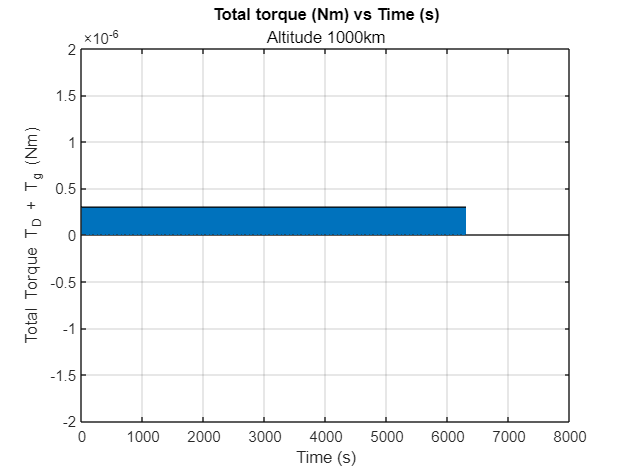

Required momentum store for 1336km is 0.0005454 kgm^2s^-1


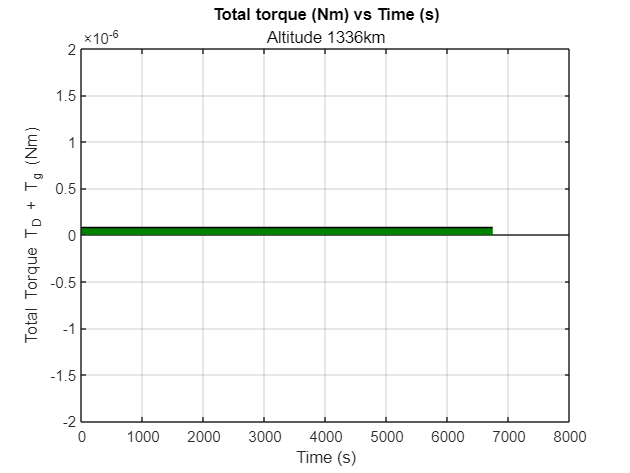

Required momentum store for 2000km is 4.681e-05 kgm^2s^-1


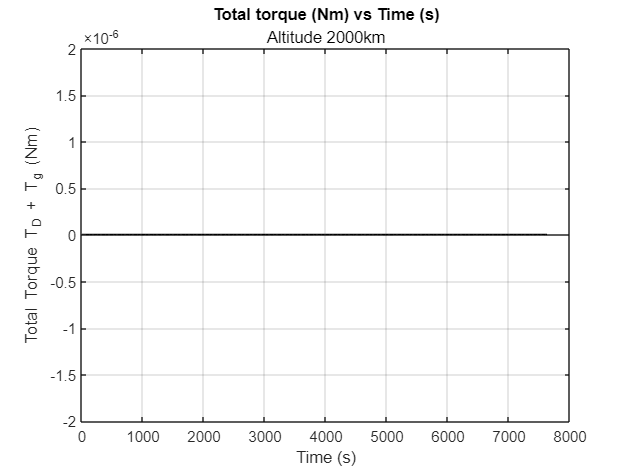

    if i == 1
        title('Total torque (Nm) vs Time (s)', 'Altitude 1000km');
    elseif i == 2
        colororder([0 0.5 0]);
        title('Total torque (Nm) vs Time (s)', 'Altitude 1336km');
    elseif i == 3
        colororder([1 0 1]);
        title('Total torque (Nm) vs Time (s)', 'Altitude 2000km');
    end
end

### Discussion

- If the centre of pressure was aligned in every axis with the centre of mass, there would never be any torque due to atmospheric drag, however this is a difficult problem to fix as the only way this would be possible is if the spacecraft was a sphere, such that any force acting on the spacecraft would be acting directly through the centre of mass at any orientation. A more practical solution would be to angle the spacecraft in such a way that the centre of pressure and the centre of mass are aligned in the direction of velocity. In this scenario, there would have to be constant adjustments made by the reaction wheels to very slowly turn the spacecraft as it travels along the orbit. For this to be possible, however, the reaction wheels would have to extremely precise and powerful enough, which would likely drive up component costs and mass, thereby increasing launch cost and fuel requirements. Additionally, there would have to be large redesigns of the structure of the spacecraft if a surface that is perfectly symmetrical in each axis does not exist on the spacecraft, and even if such a surface exists, it would have to be a surface that can point towards the velocity vector, which might not be possible if that surface already has sensitive equipment like antennas or science instruments that have to point in a certain direction. 

- If the centre of solar radiation pressure is aligned with the centre of mass, then the exclusion of this term is valid. It is unlikely that this is the case, however, so for a higher level analysis, it would be necessary to consider solar radiation pressure. Solar radiation pressure is generally quite small, particularly if there are no extendable solar arrays, which are usually the primary cause of significant disturbances due to this kind of pressure. Furthermore, solar radiation pressure is cyclic, meaning that any small effects that it does have on the spacecraft will likely be cancelled out by the start of the next orbit, assuming constant orientation to the earth, so there is likely very little need to consider its effects on the mass of fuel required. Magnetic field torque, on the other hand, I believe should be considered, particularly due to the inclination of the chosen orbit. The magentic field torque is most significant at the poles, being twice as effective than at the equator. The spacecraft is orbit at a 66 degree inclination, so not only will the poles have considerable disturbances on the total torque on the spacecraft, but it will also vary in intensity throughout an orbit. For this reason, I don't believe it is valid to neglect magnetic field torque from even a simple analysis. 

- Looking at the graph showing total torque for the mission's altitude of 1336km shows that the maximum torque is roughly $2*{10}^{-5} \;\textrm{Nm}$, requiring a momentum store of $0\ldotp 00055\;\textrm{Nms}$. As I mentioned previously, this momentum store is likely to be a 33% understimation, so I will assume that, with a 10% safety margin, the ADCS will require roughly $0\ldotp 000825\;\textrm{Nms}$. After applying the necessary filters of minimum torque and momentum store into https://www.satnow.com/search/reaction-wheels, there was only one reaction wheel available. This reaction wheel is the CW0017 CubeSpace Satellite Systems wheel with an available torque output of $2\ldotp 5*{10}^{-4} \;\textrm{Nm}$ and momentum store of $0\ldotp 00177\;\textrm{Nms}$. This reaction wheel requires up to 0.58W and as little as 0.15W and can operate between -20 and 80 degrees celsius. This makes it an excellent fit for the spacecraft as also only weighs 60 grams. 

### Functions

### Task 3 - Maximum Torque due to Gravity

#### Get max torque due to gravity

This function finds the maximum torque for each altitude and saves this value into an array which has its indices corresponding to the **altitudes** array, meaning that the first index in the gravity torque array **T_g** will be the gravity torque for the altitude in the first index of the **altitudes** array. 

### Task 4 - Create T_g Function

function [T_g] = get_T_g(I_zz, I_yy, altitudes, mu, R_earth)

This function uses both mass moments of inertia, the gravitational parameter of earth, the radius of the earth, and the array of altitudes to find gravity torque. Using array multiplication in MATLAB, it is possible use an array to create another array with other variables that are scalar values. 

### Task 5 - 'altitudes' Array

As previously mentioned, there is no need to write a loop to yield values for gravity torque because everything is being stored in an array. Rather than having three separate variables of gravity torque, one for each altitude, I can create a gravity torque array and store the values of gravity torque for each altitude in their respective index. 

### Task 6 - Find Gravity Torque

To find the maximum gravity torque, it is necessary to assume the worst case scenario for roll angle θ in the following equation which was defined in Task 2.  

Equation (9.6): 


$$T_{\textrm{Qg}} =\left(\frac{3\mu }{2R^3 }\right)\left|I_{\textrm{ZZ}} -I_{\textrm{YY}} \right|\sin \left(2\theta \right)$$


When roll angle θ is 45 degrees, sin(2θ) is 1, and since sinusoidal functions do not exceed 1, this is its maximum value. 

T_g = (3.*mu./(2.*(R_earth+altitudes).^3)).*(abs(I_zz-I_yy));
end

This function can now be called and will retrieve the maximum value of gravity torque as long as all necessary inputs are given. 

### Task 7 - Generating the Maximum Torque due to Drag Function

#### Get max torque due to drag

The approach to this function is the same as the one for **get_T_g**, and it can be called in the same way. 

function [T_D] = get_T_D(rho_alts, C_d, area_surface, vel_alts, CgToCp)

I make use of array multiplication in MATLAB to create a drag torque array called **T_D**, which stores a value of drag torque for each altitude. The only difference between this function and the gravity torque one is that this function uses two arrays: the **rho_alts** array, containing a density for each given altitude, and a **vel_alts** array, containing a velocity for each given altitude. 

T_D = 0.5.*rho_alts.*C_d.*(vel_alts.^2).*area_surface.*CgToCp;
end